% Definição dos tamanhos das tabelas hash
hashTableSizes = [5*1e5 1e6 2*1e6];

% Número de strings a serem geradas
N = 1e5;

% Caracteres utilizados na geração das strings
chars = 'abcdefghijklmnopqrstuvwxyz';

% Probabilidades dos caracteres a partir de um arquivo 'prob_pt.txt'
prob_chars = load("prob_pt.txt");

% Limites para o tamanho das strings geradas
min = 6;
max = 20;

% Geração das strings aleatórias
strings = randStringArray(N, min, max, chars, prob_chars);

% Inicialização das estruturas para resultados
resultados = cell(4,3);
colisoes = zeros(4,3);
tempos = zeros(4,3);
codes1 = zeros(4, N);
codes2 = zeros(4, N);
codes3 = zeros(4, N);

% Loop para iterar sobre os tamanhos das tabelas hash
for i = 1:3
    fprintf("string2hash(djb2):\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para iterar sobre as strings geradas
    for j = 1:N
        code = mod(string2hash(strings{j}, 'djb2'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Atribuição dos códigos de hash às variáveis correspondentes
        if i == 1
            codes1(1, j) = code;
        elseif i == 2
            codes2(1, j) = code;
        else
            codes3(1, j) = code;
        end
    end
    resultados{1, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(1, i) = numColisoes;
    tempos(1, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(1, i));
    fprintf("------------------------------------------------------------------")
    % Repetição similar para as outras funções de hash
    fprintf("string2hash(sdbm):\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = mod(string2hash(strings{j}, 'sdbm'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(2, j) = code;
        elseif i == 2
            codes2(2, j) = code;
        else
            codes3(2, j) = code;
        end
    end
    resultados{2, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(2, i) = numColisoes;
    tempos(2, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(2, i));
    fprintf("------------------------------------------------------------------")
    fprintf("hashstring:\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = hashstring(strings{j}, hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(3, j) = code;
        elseif i == 2
            codes2(3, j) = code;
        else
            codes3(3, j) = code;
        end
    end
    resultados{3, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(3, i) = numColisoes;
    tempos(3, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(3, i));
    fprintf("------------------------------------------------------------------")
    fprintf("DJB31MA:\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = mod(DJB31MA(strings{j}, 13), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(4, j) = code;
        elseif i == 2
            codes2(4, j) = code;
        else
            codes3(4, j) = code;
        end
    end
    resultados{4, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(4, i) = numColisoes;
    tempos(4, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(4, i));
    fprintf("------------------------------------------------------------------")
    fprintf("\n\n\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 18115


	Elapsed time: 0.188223



------------------------------------------------------------------

string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 18223


	Elapsed time: 0.289361



------------------------------------------------------------------

hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35891


	Elapsed time: 1.158282



------------------------------------------------------------------

DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 17760


	Elapsed time: 0.123735



------------------------------------------------------------------

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9530


	Elapsed time: 0.171642



------------------------------------------------------------------

string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9643


	Elapsed time: 0.328619



------------------------------------------------------------------

hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 29352


	Elapsed time: 2.510708



------------------------------------------------------------------

DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9169


	Elapsed time: 0.343225



------------------------------------------------------------------

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 4858


	Elapsed time: 0.408232



------------------------------------------------------------------

string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4857


	Elapsed time: 0.593666



------------------------------------------------------------------

hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 22952


	Elapsed time: 2.420574



------------------------------------------------------------------

DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 4659


	Elapsed time: 0.223356



------------------------------------------------------------------

Momentos:


	Momento de ordem 2: 2.399080e-01
	Momento de ordem 5: 1.003640e+00
	Momento de ordem 10: 1.320961e+02


Número de colisões: 18115


Tempo de execução: 0.188223

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.401560e-01
	Momento de ordem 5: 1.013360e+00
	Momento de ordem 10: 1.417516e+02


Número de colisões: 18223


Tempo de execução: 0.289361

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.396640e-01
	Momento de ordem 5: 1.395302e+01
	Momento de ordem 10: 1.479854e+05


Número de colisões: 35891


Tempo de execução: 1.158282

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.390480e-01
	Momento de ordem 5: 9.858800e-01
	Momento de ordem 10: 1.342166e+02


Número de colisões: 17760


Tempo de execução: 0.123735

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.749150e-02
	Momento de ordem 5: 8.505312e-03
	Momento de ordem 10: 1.476046e-02


Número de colisões: 9530


Tempo de execução: 0.171642

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.751850e-02
	Momento de ordem 5: 8.575625e-03
	Momento de ordem 10: 1.646769e-02


Número de colisões: 9643


Tempo de execução: 0.328619

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.949150e-02
	Momento de ordem 5: 1.804137e-01
	Momento de ordem 10: 5.725516e+01


Número de colisões: 29352


Tempo de execução: 2.510708

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.740700e-02
	Momento de ordem 5: 8.396563e-03
	Momento de ordem 10: 1.588313e-02


Número de colisões: 9169


Tempo de execução: 0.343225

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.831111e-03
	Momento de ordem 5: 3.693416e-04
	Momento de ordem 10: 3.842470e-05


Número de colisões: 4858


Tempo de execução: 0.408232

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.831222e-03
	Momento de ordem 5: 3.697119e-04
	Momento de ordem 10: 3.890737e-05


Número de colisões: 4857


Tempo de execução: 0.593666

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 7.878667e-03
	Momento de ordem 5: 6.916687e-03
	Momento de ordem 10: 1.602801e-01


Número de colisões: 22952


Tempo de execução: 2.420574

------------------------------------------------------------------------------------------


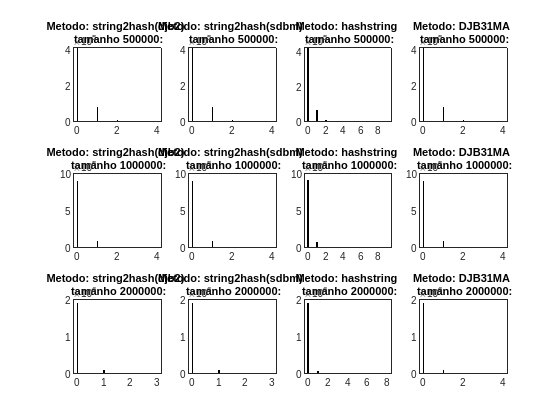

Momentos:


	Momento de ordem 2: 5.820667e-03
	Momento de ordem 5: 3.655761e-04
	Momento de ordem 10: 4.691216e-05


Número de colisões: 4659


Tempo de execução: 0.223356

------------------------------------------------------------------------------------------



% Configuração dos títulos para os histogramas
titles = {'string2hash(djb2)', 'string2hash(sdbm)', 'hashstring', 'DJB31MA'};
momentos = zeros(3, 10);

% Loop para plotar histogramas e calcular momentos
for i = 1:3
    for j = 1:4
        subplot(3, 4, 4 * (i - 1) + j);
        histogram(resultados{j, i}, 100);
        title(sprintf("Metodo: %s \n tamanho %d:", titles{j}, hashTableSizes(i)));

        fprintf("Momentos:\n");
        valores = resultados{j, i} / i;
        [contagem, valores] = groupcounts(valores);
        for n = [2, 5, 10]       
            En = 0;
            for x = 1:length(valores)
                En = En + ((valores(x)^n) * (contagem(x) / hashTableSizes(i)));
            end
            momentos(i, n) = En;
            fprintf("\tMomento de ordem %d: %d\n", n, En);
        end

        fprintf("\n");
        fprintf("Número de colisões: %d\n", colisoes(j, i));
        


        fprintf("Tempo de execução: %f", tempos(j, i));
        fprintf("\n");
        fprintf("------------------------------------------------------------------------------------------\n")
    end
end